# Exercise 2 regbot

## Plot data from the log txt file

data_wu = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\regbot_log_6_wu.txt');
data_wu = fillmissing(data_wu, 'nearest');
data_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\regbot_log_6_wd.txt');
data_wd = fillmissing(data_wd, 'nearest');
data_wu_after = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\regbot_log_6_wd_1.txt');
data_wu_after = fillmissing(data_wu_after, 'nearest');

[t_wu,u_L_wu,u_R_wu,v_L_wu,v_R_wu,T_s_wu] = get_data(data_wu);
[t_wd,u_L_wd,u_R_wd,v_L_wd,v_R_wd,T_s_wd] = get_data(data_wd);
[t_wu_after,u_L_wu_after,u_R_wu_after,v_L_wu_after,v_R_wu_after,T_s_wu_after] = get_data(data_wu_after);

idd_L_wu = iddata(v_L_wu,u_L_wu,T_s_wu);
idx = find(u_L_wd >= 4,1,'first')

idx = 751

idx = idx - 20

idx = 731

idd_L_wd = iddata(v_L_wd(idx:end),u_L_wd(idx:end),T_s_wd);
idd_L_wu_after = iddata(v_L_wu_after,u_L_wu_after,T_s_wu_after);
G_wu_L_wu = tfest(idd_L_wu,2,0)  

G_wu_L_wu =
 
  From input "u1" to output "y1":
         4.006e04
  -----------------------
  s^2 + 8031 s + 1.351e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "idd_L_wu".
Fit to estimation data: 95.56%                       
FPE: 0.0005708, MSE: 0.0005669                       


G_wu_L_wd = tfest(idd_L_wd,2,0) 

G_wu_L_wd =
 
  From input "u1" to output "y1":
       -0.003732
  --------------------
  s^2 + 20.5 s + 84.86
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "idd_L_wd".
Fit to estimation data: -725.4%                      
FPE: 0.7309, MSE: 0.7209                             


G_wu_after = tfest(idd_L_wu_after,2,0) 

G_wu_after =
 
  From input "u1" to output "y1":
           7.345e04
  ---------------------------
  s^2 + 1.488e04 s + 2.511e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                    
Estimated using TFEST on time domain data "idd_L_wu_after".
Fit to estimation data: 94.33%                             
FPE: 0.0009087, MSE: 0.0009024                             


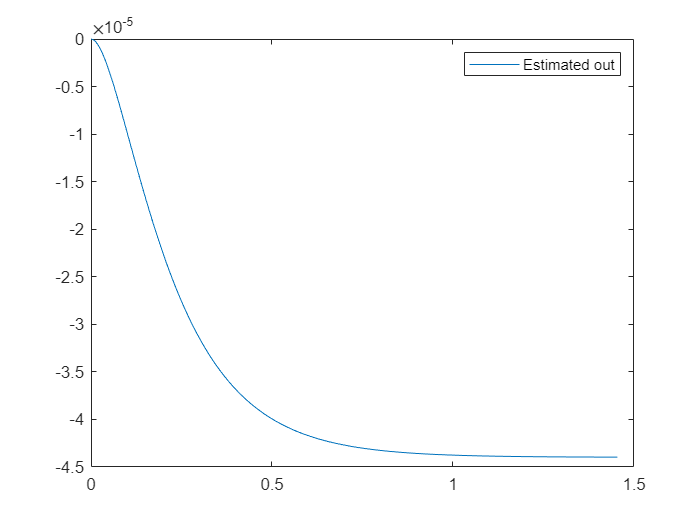



[y_A,t_A] = step(G_wu_L_wd,t(end));
figure
plot(t_A,y_A);
hold on
hold off
legend('Estimated out','Measured out');

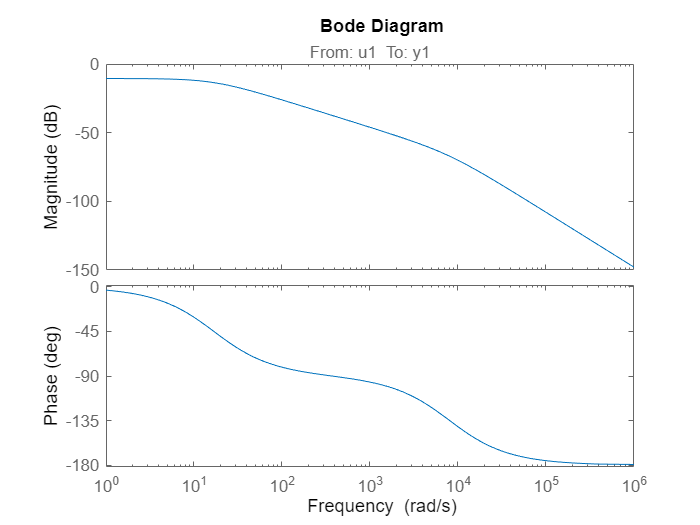



bode(G_wu_L_wu)

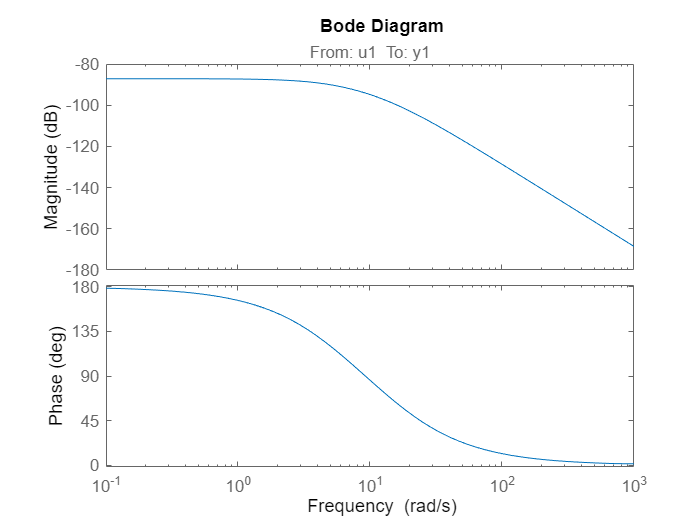

bode(G_wu_L_wd)

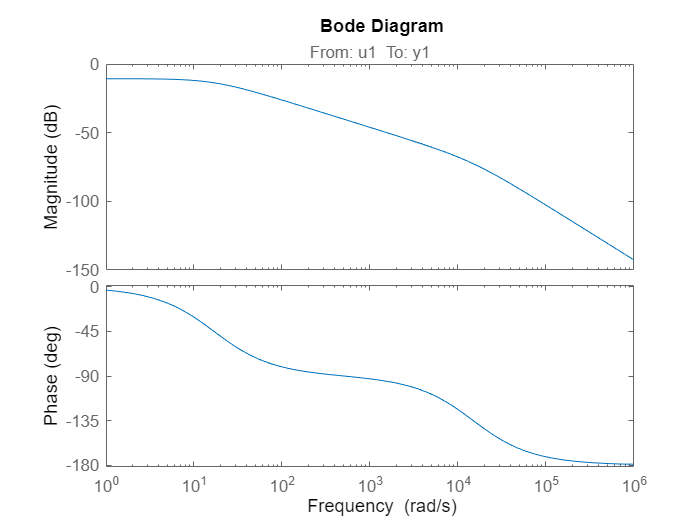

bode(G_wu_after)

%From previous exercise
Kp = 1

Kp = 1


G_ol = Kp*G_wu_L_wu

G_ol =
 
  From input "u1" to output:
         4.006e04
  -----------------------
  s^2 + 8031 s + 1.351e05
 
Continuous-time transfer function.




a = margin(G_ol) %This means it is stable?

a = Inf


filter = tf(10,1+10)

filter =
 
  0.9091
 
Static gain.




G_ol = G_ol *  filter

G_ol =
 
             4.006e05
  ------------------------------
  11 s^2 + 8.834e04 s + 1.487e06
 
Continuous-time transfer function.



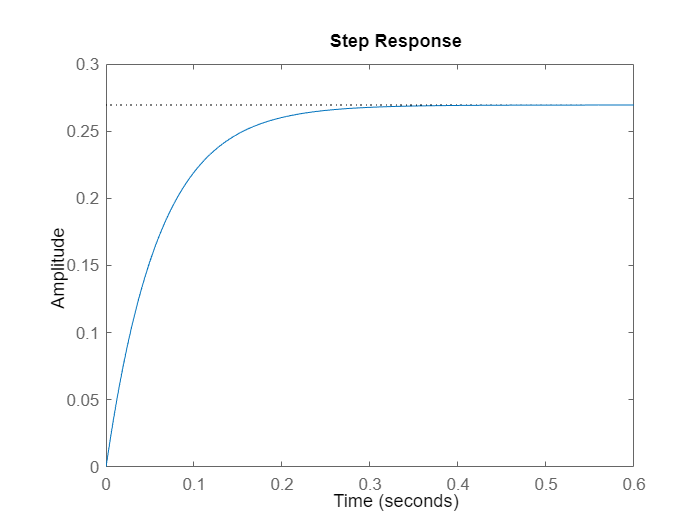


step(G_ol)

G_cl = Kp * G_wu_L_wu / (1 + G_ol)

G_cl =
 
             4.406e05 s^2 + 3.539e09 s + 5.954e10
  -----------------------------------------------------------
  11 s^4 + 1.767e05 s^3 + 7.129e08 s^2 + 2.709e10 s + 2.55e11
 
Continuous-time transfer function.



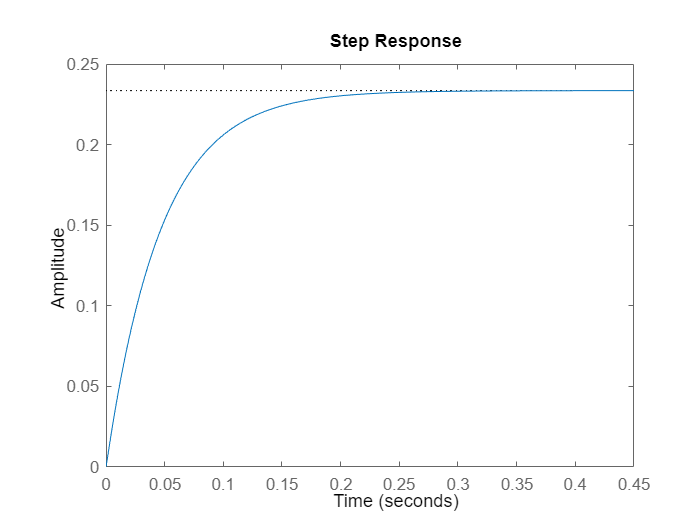

step(G_cl)

function [t,u_L,u_R,v_L,v_R,T_s] = get_data(data)
    t = table2array(data(:,1));     % time stamps
    u_L = table2array(data(:,8));   % left motor voltage
    u_R = table2array(data(:,9));   % right motor voltage
    v_L = table2array(data(:,10));  % left motor velocity 
    v_R = table2array(data(:,11));  % right motor velocity
    T_s = t(2) - t(1);              % compute sampling time
end